s = 100;
clusterCount = 4;
maxDensity = 5;
maxRadius = 20;

COMs = zeros(clusterCount,2);
D = randi([0,2], 100, 100);

pts = linspace(0, s, s);
for i = 1:clusterCount
    COMs(i,1) = randi([maxRadius,s-maxRadius]);
    COMs(i,2) = randi([maxRadius,s-maxRadius]);
    scatter(COMs(i,1),COMs(i,2),'b*');
    hold on;
end
axis equal;
set(gca, 'XLim', pts([1 end]), 'YLim', pts([1 end]));

D = randi([0,1],s,s);

for n = 1:clusterCount
    for i = -maxRadius:maxRadius
        for j = -maxRadius:maxRadius
            densityPoint = [COMs(n,1)+i,COMs(n,2)+j];
            clusterPoint = [COMs(n,1),COMs(n,2)];
            distance = norm(clusterPoint-densityPoint);
            
            if (distance <= maxRadius ...
                    && densityPoint(1,1) > 0 && densityPoint(1,1) < s ...
                    && densityPoint(1,2) > 0 && densityPoint(1,2) < s)
                addingAmount = ceil((1 - distance / maxRadius) * maxDensity);
                if (distance == 0)
                    addingAmount = maxDensity;
                end
                D(COMs(n,1)+i,COMs(n,2)+j) = D(COMs(n,1)+i,COMs(n,2)+j) + addingAmount;
            end
        end
    end
end

D

D =      0     1     1     0     1     0     1     0     0     1     0     1     0     1     0     1     0     0     1     0     1     0     0     0     1     1     1     0     0     1     1     1     1     0     1     0     0     1     0     0     0     0     1     1     0     1     0     0     1     1
     1     0     1     1     0     0     1     0     1     0     0     1     1     0     0     1     0     0     1     1     1     1     1     0     0     1     1     1     0     0     1     1     1     1     1     0     0     1     1     0     0     0     1     1     1     0     1     1     0     0
     0     0     0     0     0     0     0     0     1     0     1     0     0     1     0     0     1     1     0     1     0     0     0     1     1     1     0     0     1     1     0     1     0     0     1     1     1     1     1     1     1     0     0     0     1     1     0     0     1     1
     1     0     1     1     0     1     0     0     0     0     1     0     0     0     0   

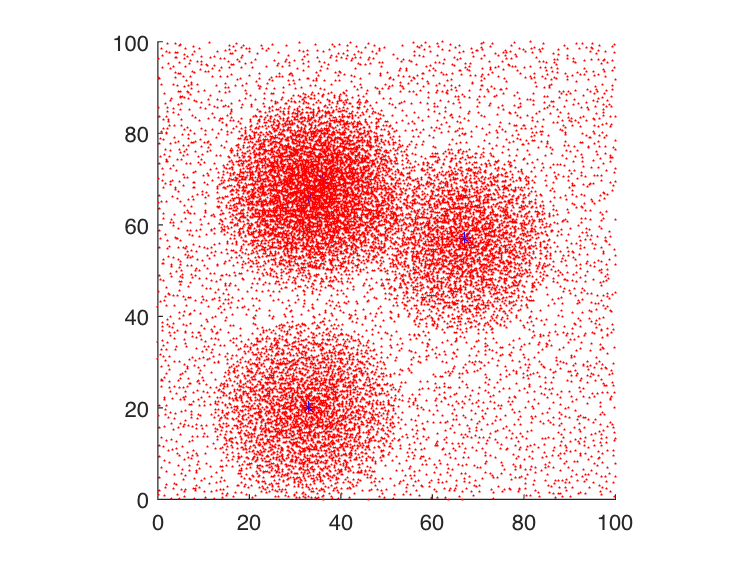


x=0+rand(1,D(1,1))*(1-0);
y=0+rand(1,D(1,1))*(1-0);

for i = 1:s
    for j = 1:s
        xN = ((i-1)+rand(1,D(i,j))*(i-(i-1)));
        yN = (j-1)+rand(1,D(i,j))*(j-(j-1));
        x = horzcat(x, xN);
        y = horzcat(y, yN);
    end
end

% Plot data:
scatter(x, y, 1, 'r.');